%1.2投资收益最大化
clear
a=0;
hold on 
while a<0.05
f=[-0.27;-0.19;-0.185;-0.185;-0.05];
A=[  0.025 0 0 0 0 
     0 0.015 0 0 0 
     0 0 0.055 0 0
     0 0 0 0.026 0];
b=a*ones(4,1);
Aeq=[1.01 1.02 1.045 1.065 1];
beq=(1);
lb=zeros(5,1);
[x,fval]=linprog(f,A,b,Aeq,beq,lb);
plot(x,-fval,'*k');
a=a+0.001;
end

Optimal solution found.

Optimal solution found.

Optimal solution found.

Optimal solution found.

Optimal solution found.

Optimal solution found.

Optimal solution found.

Optimal solution found.

Optimal solution found.

Optimal solution found.

Optimal solution found.

Optimal solution found.

Optimal solution found.

Optimal solution found.

Optimal solution found.

Optimal solution found.

Optimal solution found.

Optimal solution found.

Optimal solution found.

Optimal solution found.

Optimal solution found.

Optimal solution found.

Optimal solution found.

Optimal solution found.

Optimal solution found.

Optimal solution found.

Optimal solution found.

Optimal solution found.

Optimal solution found.

Optimal solution found.

Optimal solution found.

Optimal solution found.

Optimal solution found.

Optimal solution found.

Optimal solution found.

Optimal solution found.

Optimal solution found.

Optimal solution found.

Optimal solution found.

Optimal solution found.



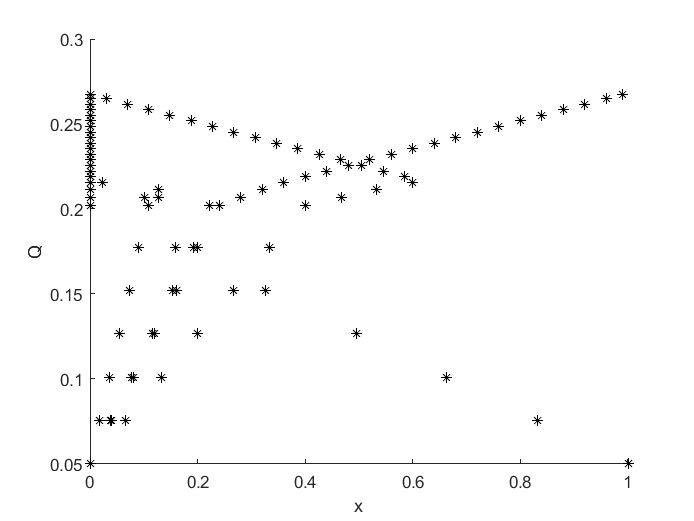

xlabel('x'),ylabel('Q');

%qes1.1
clear
f=[-3 1 1];
A=[ 1 -2 1
    4 -1 -2
    -1 0 0
    0 -1 0
    0 0 -1 ];
b=[11;-3;0;0;0];
Aeq=[-2 0 1];
beq=(1);
lb=zeros(3,1);
[x,fval,exitflag,output,lambda]=linprog(f,A,b,Aeq,beq,lb);

Optimal solution found.



disp(x);

    4.0000
    1.0000
    9.0000



disp(fval);

   -2.0000



disp(exitflag);

     1



disp(output);

         iterations: 2
    constrviolation: 8.8818e-16
            message: 'Optimal solution found.'
          algorithm: 'dual-simplex'
      firstorderopt: 5.9212e-16



disp(lambda);

      lower: [3×1 double]
      upper: [3×1 double]
      eqlin: -0.6667
    ineqlin: [5×1 double]



%qes1.2
clear
%x=u-v,abs(x)=u+v
f=[1 2 3 4];
f=[f,f];
Aeq=[1 -1 -1 1
     1 -1 1 -3
     1 -1 -2 3];
Aeq=[Aeq,-Aeq];
beq=[0;1;-0.5];
lb=zeros(8,1);
[y,fval,exitflag,output,lambda]=linprog(f,[],[],Aeq,beq,lb);

Optimal solution found.



x=y(1:4)-y(5:end);
disp(x);

    0.2500
         0
         0
   -0.2500



disp(fval);

    1.2500



disp(exitflag);

     1



disp(output);

         iterations: 2
    constrviolation: 0
            message: 'Optimal solution found.'
          algorithm: 'dual-simplex'
      firstorderopt: 8.8818e-16



disp(lambda);

      lower: [8×1 double]
      upper: [8×1 double]
      eqlin: [3×1 double]
    ineqlin: []



%qes1.3
clear
f=[-1.00 -1.65 -2.30];
A=[ 5 10 0
    7 9 12
    6 8 0
    4 0 11
    7 0 0 ];
b=[6000;10000;4000;7000;4000];
lb=zeros(3,1);
[x,fval,exitflag,output,lambda]=linprog(f,A,b,[],[],lb);

Optimal solution found.



disp(x);

         0
  262.6263
  636.3636



disp(fval);

  -1.8970e+03



disp(exitflag);

     1



disp(output);

         iterations: 3
    constrviolation: 0
            message: 'Optimal solution found.'
          algorithm: 'dual-simplex'
      firstorderopt: 3.3348e-13



disp(lambda);

      lower: [3×1 double]
      upper: [3×1 double]
      eqlin: []
    ineqlin: [5×1 double]



%qes1.4
clear
f=[-3100 -3800 -3500 -2850];
A=[ 18 15 23 12
    480 650 580 390];
b=[10+16+8;6800+8700+5300];
lb=zeros(4,1);
[x,fval,exitflag,output,lambda]=linprog(f,A,b,[],[],lb);

Optimal solution found.



disp(x);

         0
    2.2667
         0
         0



disp(fval);

  -8.6133e+03



disp(exitflag);

     1



disp(output);

         iterations: 3
    constrviolation: 7.1054e-15
            message: 'Optimal solution found.'
          algorithm: 'dual-simplex'
      firstorderopt: 1.8000e-12



disp(lambda);

      lower: [4×1 double]
      upper: [4×1 double]
      eqlin: []
    ineqlin: [2×1 double]

